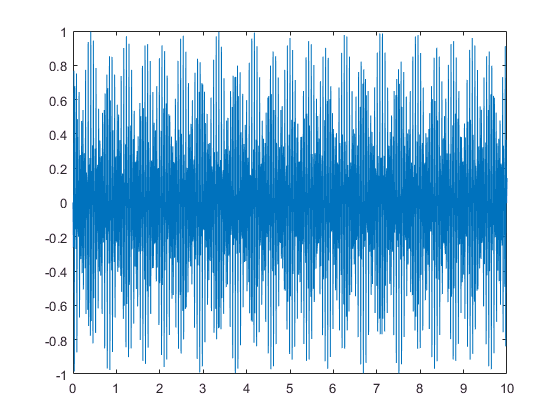

t=0:0.01:10;
signal=sin(50*t).*sin(1000*t);

plot(t,signal);

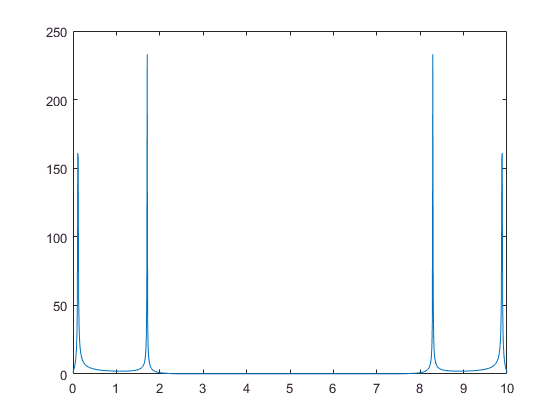

plot(t,abs(fftshift(fft(signal))));

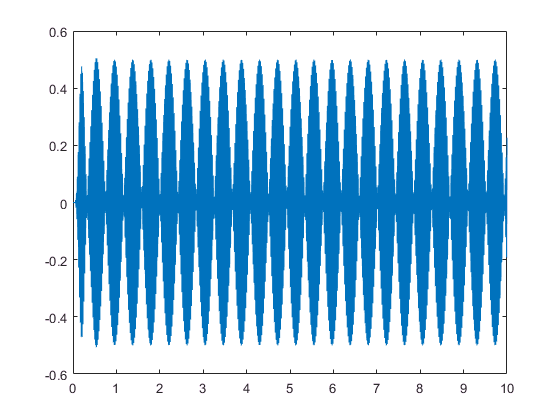


[b,a] = butter(6,0.9,'high');
plot(t,filter(b,a,signal));

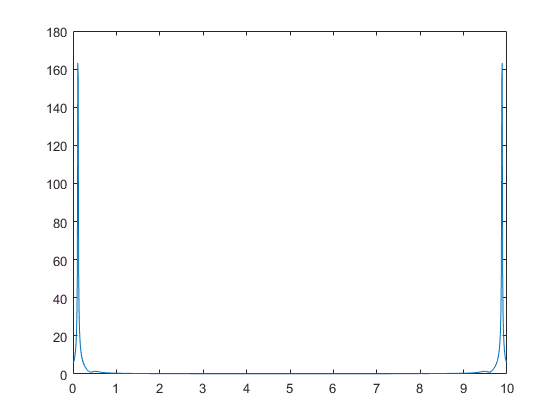

plot(t,abs(fftshift(fft(filter(b,a,signal)))));